## 6.

    a)

   %  1    2    3    4    5
T = [0.8  0     0   0.3   0;  %1
     0.2  0.6   0   0.2   0;  %2
     0    0.3   1    0    0;  %3
     0    0.1   0   0.4   0;  %4
     0    0     0   0.1   1]; %5

fprintf('Matriz de Transição');

Matriz de Transição

disp(T);

    0.8000         0         0    0.3000         0
    0.2000    0.6000         0    0.2000         0
         0    0.3000    1.0000         0         0
         0    0.1000         0    0.4000         0
         0         0         0    0.1000    1.0000



###     b) Gráfico em função dos passos

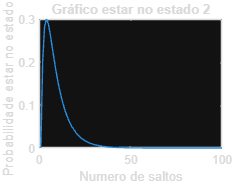

n = 1:100;
prob_2 = zeros(1,length(n));
x0 = zeros(5,1);
x0(1) = 1;

for i = n
    xn = T^(i-1)*x0;
    prob_2(i) = xn(2);
end

plot(n,prob_2);
title('Gráfico estar no estado 2');
xlabel('Numero de saltos');
ylabel('Probabilidade estar no estado 2');

####     c) Gráfico a começar no  1, estar no 3 e 5 ao fim de n transições

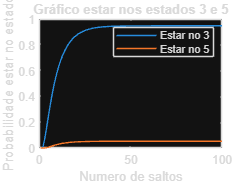

n = 100;
prob_3 = zeros(1,n);
x0_3 = zeros(5,1);
x0_5 = zeros(5,1);

x0_3(1) = 1;
x0_5(1) = 1;
prob_5 = zeros(1,n);

for i = 1:n
    xn_3 = T^(i-1)*x0_3;
    prob_3(i) = xn_3(3);

    xn_5 = T^(i-1)*x0_5;
    prob_5(i) = xn_5(5);
end

plot(1:n,prob_3);
hold on
plot(1:n, prob_5);
legend('Estar no 3','Estar no 5')
title('Gráfico estar nos estados 3 e 5');
xlabel('Numero de saltos');
ylabel('Probabilidade estar no estado');

###     d) Calcular a matriz Q

   %  1    2     4     3    5
TC = [0.8  0     0.3   0   0;  %1
      0.2  0.6   0.2   0   0;  %2
      0    0.1   0.4   0   0;  %4
      0    0.3   0     1   0;  %3
      0    0     0.1   0   1]; %5

[TCm,Qm,Fm] = canonic_maker(T);
 
Q = TC(1:3, 1:3);
fprintf('Matriz Q');

Matriz Q

disp(Q);

    0.8000         0    0.3000
    0.2000    0.6000    0.2000
         0    0.1000    0.4000



###     e) Matriz fundamental

% matriz identidade
I = eye(length(Q));
F = inv(I - Q);
fprintf('Matriz Fundamental F');

Matriz Fundamental F

disp(F);

    5.7895    0.7895    3.1579
    3.1579    3.1579    2.6316
    0.5263    0.5263    2.1053



### Teste de canonic maker, cheat code

if isequal(TCm, TC) && isequal(Qm, Q) && isequal(Fm, F)
    fprintf('Shé boi ganda script');
else
    fprintf('Ganda burro');
end

Shé boi ganda script

####     f) Média de passos até absorção

E = sum(F);

fprintf("Média de passos até absorção\n Começando no estado 1: %.4f\n Começando no estado 2: %.4f\n Começando no estado 4: %.4f\n ", E);

Média de passos até absorção
 Começando no estado 1: 9.4737
 Começando no estado 2: 4.4737
 Começando no estado 4: 7.8947
 

    g) A começar no 1, a probabilidade de absorção do estado 3 e no 5

R = TC(4:5,1:3);
B = R*F;

fprintf('Probabiliade de começando no estado 1:\n Absorção do estado 3: %.4f\n Absorção do estado 5: %.4f', B(:,1));

Probabiliade de começando no estado 1:
 Absorção do estado 3: 0.9474
 Absorção do estado 5: 0.0526